# PF: C1

% Script para el primer ejercicio de la práctica final de VO
% Claudia Gallego i Paula Esteve | Gener 2025
clear all;
close all;
clc;

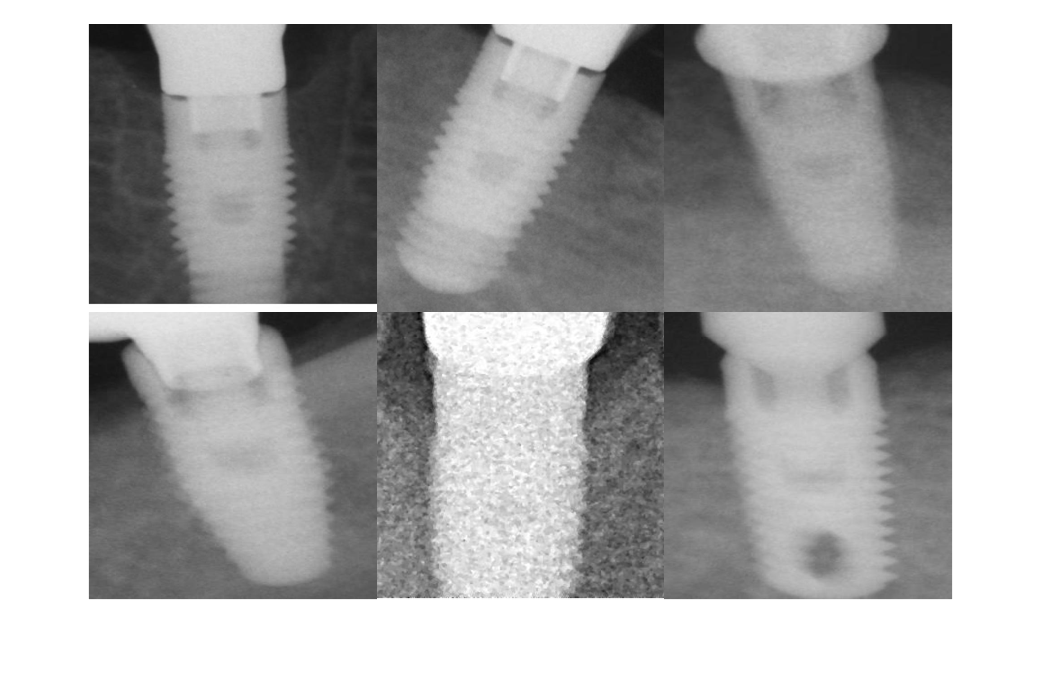

% Primero es necesario hacer una visualización de unas cuantas muestras para
% hacernos una idea de con qué tipos de imágenes trabajamos y qué características.
% tienen, ya que esto afectará al procesamiento que debemos aplicar.

imp1 = imread("Implantes/1.jpg");
imp2 = imread("Implantes/50.jpg");
imp3 = imread("Implantes/100.jpg");
imp4 = imread("Implantes/150.jpg");
imp5 = imread("Implantes/200.jpg");
imp6 = imread("Implantes/69.jpg");

montage({imp1, imp2, imp3, imp4, imp5, imp6})


% Así en esta primera visualización podemos ver que hay imágenes mucho más
% nítidas, con diferentes niveles de contraste y de granularidad.

% Carpetas para guardar las imagenes obtenidas
carpeta_entrada = 'Implantes/';
carpeta_segmentada = 'Resultados/';
carpeta_bbox = 'bbounding_box/';

% Bucle encargado de hacer la classificacion de outliers

archivos_imagenes = dir(fullfile(carpeta_entrada, '*.jpg'));
num_imagenes = length(archivos_imagenes);

metricas = struct('nombre', {}, 'contraste', {}, 'uniformidad', {}, 'suavidad', {}, 'entropia', {}, 'concentracion', {});

for i = 1:num_imagenes
    img = imread(fullfile(carpeta_entrada, archivos_imagenes(i).name));
    img_gray = rgb2gray(img);
    
    % Métricas
    contraste = std(double(img_gray(:))) / mean(double(img_gray(:)));
    histograma = imhist(img_gray) / numel(img_gray);
    uniformidad = sum(histograma.^2);
    suavidad = 1 - (1 / (1 + std2(img_gray)^2));
    entropia = entropy(img_gray);
    concentracion = sum(histograma(round(0.25 * 255):round(0.75 * 255))) / sum(histograma);
    
    % Guardar resultados
    metricas(i).nombre = archivos_imagenes(i).name;
    metricas(i).contraste = contraste;
    metricas(i).uniformidad = uniformidad;
    metricas(i).suavidad = suavidad;
    metricas(i).entropia = entropia;
    metricas(i).concentracion = concentracion;
end

% Mostrar resultados (percentil 5 y 95)
percentil_5_contraste = prctile([metricas.contraste], 2);
percentil_95_contraste = prctile([metricas.contraste], 98);
percentil_5_uniformidad = prctile([metricas.uniformidad], 2);
percentil_95_uniformidad = prctile([metricas.uniformidad], 98);
percentil_5_entropia = prctile([metricas.entropia], 2);
percentil_95_entropia = prctile([metricas.entropia], 98);

fprintf('\nPercentil 5 y 95:\n');


Percentil 5 y 95:


fprintf('Contraste - 5%%: %.4f, 95%%: %.4f\n', percentil_5_contraste, percentil_95_contraste);

Contraste - 5%: 0.2531, 95%: 0.6423


fprintf('Uniformidad - 5%%: %.4f, 95%%: %.4f\n', percentil_5_uniformidad, percentil_95_uniformidad);

Uniformidad - 5%: 0.0060, 95%: 0.0148


fprintf('Entropía - 5%%: %.2f, 95%%: %.2f\n', percentil_5_entropia, percentil_95_entropia);

Entropía - 5%: 6.67, 95%: 7.59



candidatos_outliers = {};  % Cambiar a celda de cadenas

for i = 1:num_imagenes
    % Verificar si la imagen está fuera del percentil 5 o 95 en alguna métrica
    if (metricas(i).contraste < percentil_5_contraste || metricas(i).contraste > percentil_95_contraste) || ...
       (metricas(i).uniformidad < percentil_5_uniformidad || metricas(i).uniformidad > percentil_95_uniformidad) || ...
       (metricas(i).entropia < percentil_5_entropia || metricas(i).entropia > percentil_95_entropia)
        candidatos_outliers = [candidatos_outliers, metricas(i).nombre];
    end
end

fprintf('\nOutliers encontrados: %s\n', strjoin(candidatos_outliers, ', '));


Outliers encontrados: 108.jpg, 112.jpg, 115.jpg, 125.jpg, 126.jpg, 14.jpg, 140.jpg, 172.jpg, 175.jpg, 179.jpg, 184.jpg, 42.jpg, 54.jpg, 68.jpg, 7.jpg, 71.jpg


% Al ser imágenes en escala de grises, las cuales, el objeto de interés
% tiene un nivel de intensidad respecto al del fondo, es adiente aplicar
% segmentación por "thresholding".

% Creamos una primera función de segmentación, basándonos en esta idea,
% Primero nos aseguramos de que efectivamente estén en escala de grises y
% umbralizamos con el método de Otsu. Para limpiar cualquier borde.
% Aplicamos las operaciones morfológicas imopen (para eliminar ruido pequeño).
% i imclose (cierra huecos). Por último, rellenamos los agujeros internos que se
% pueden haber generado en la máscara dado que el implante contiene zonas.
% de menor intensidad.

% Este método sirve de baseline, usamos Otsu para segmentar el implante ya
% que el implante es más brillante que el fondo y el histograma permite
% separar de manera correcta en la mayoría de los casos.

function mascara = segmentar1(img)
    if size(img, 3) == 3
        img_gray = rgb2gray(img);
    else
        img_gray = img;
    end
    nivel = graythresh(img_gray);
    mascara = imbinarize(img_gray, nivel);

    se = strel('disk', 2); 
    
    mascara = imopen(mascara, se);
    
    se_close = strel('disk', 7);
    mascara = imclose(mascara, se_close);

    mascara = imfill(mascara, 'holes');

    [etiquetas, num_objetos] = bwlabel(mascara);
   
    propiedades = regionprops(etiquetas, 'Area');
    
    if ~isempty(propiedades)
        allAreas = [propiedades.Area];
        [~, indice_mayor] = max(allAreas);
        
        %Generar la máscara solo con el objeto mayor
        mascara = (etiquetas == indice_mayor);
    end
    mascara = logical(mascara);
end

% Una vez aplicado el primer método a todas las imágenes, nos dimos cuenta
% que no todas se binarizaban correctamente, ya que se quedaba corto. Hay
% imágenes que el contraste no es tan limpio o la intensidad del implante
% no es uniforme.

% Para solucionar esto, desarrollamos un método basado en un contraste más
% agresivo y segmentación por zonas con doble umbralización.

function mascara = segmentar2(img, gamma_val, umbral1)
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    
    img = double(img);
    img = img / max(img(:)); 

    %Elevar a una potencia hace que las zonas brillantes destaquen más y
    %los valores medios/bajos se compriman. 
    img = img .^ gamma_val; 

    img = medfilt2(img, [9 9]);
    t = graythresh(img);

    % Doble umbral: uno permisivo para la cabeza y una más estricto para la
    % punta ya que normalmente hay más reflejo en la parte inferior. 
    t_permissive = umbral1 * t; 
    mask_head = imbinarize(img, t_permissive);
 
    t_strict = 0.90 * t; 
    mask_tip = imbinarize(img, t_strict);

    %Usamos mask_head para detectar en qué filas aparece "algo" del objeto.
    % Con top_row y bottom_row estimamos la altura. La línea de corte al
    % 60% (calculado de manera empírica)
    rows = any(mask_head, 2);
    top_row = find(rows, 1, 'first');
    bottom_row = find(rows, 1, 'last');
    
    altura = bottom_row - top_row;
    linea_corte = round(top_row + (altura * 0.60));
    linea_corte = max(1, min(linea_corte, size(img, 1)));
    
    % Combinamos las máscaras por regiones 
    mascara = mask_head;
    mascara(linea_corte:end, :) = mask_tip(linea_corte:end, :);
  
    t_seed = 1.8 * t; 
    highSeed = imbinarize(img, t_seed);
    
    mascara = imreconstruct(highSeed, mascara);
    mascara = imclose(mascara, strel('disk', 50));
    mascara = imfill(mascara, 'holes');
   
    mascara = bwareafilt(mascara, 1);
    
end



%Para 120

% Con los dos métodos anteriores conseguimos segmentar correctamente todos
% los implantes, a excepción de 1, el 120. El problema de esta imagen es que
% tiene un reflejo que se superpone con el implante y tiene la misma
% intensidad. Esto provoca que la segmentación tenga dos "pertuberancias" a
% los lados. Para solucionar esto utilizamos la misma lógica de doble
% umbral, tophat pero con la diferencia de que aplicamos imopen con un
% elemento estructural rectangular para intentar eliminar lo máximo posible
% de reflejo.

function mascara = segmentar4(img)
    if size(img, 3) == 3
        img_gray = rgb2gray(img);
    else
        img_gray = img;
    end

    img_filt = medfilt2(img_gray, [7 7]);
    se_tophat = strel('disk', 250);
    img_th = imtophat(img_filt, se_tophat);
    bw_strong = imbinarize(img_th, 0.38);
    bw_weak = imbinarize(img_th, 0.15);
    mascara_rec = imreconstruct(bw_strong, bw_weak);
    se_vertical = strel('rectangle', [240, 90]); 
    mascara_vertical = imopen(mascara_rec, se_vertical);
    mascara_closed = imfill(mascara_vertical, 'holes');
    mascara = bwareaopen(mascara_closed, 1000);

end


% Aqui procesamos todas las imagenes de la carpeta segun el metodo
carpeta_origen = "Implantes";
carpeta_destino = "Resultados";
mkdir(carpeta_destino); 


ids_grupo2 = [2, 3, 99, 100, 105, 137, 158, 190];
ids_grupo3 = [68, 153, 168, 179, 169];
ids_grupo4 = [120];

files = dir(fullfile(carpeta_origen, "*.jpg"));

for k = 1:length(files)
    nombre = files(k).name;
    img = imread(fullfile(carpeta_origen, nombre));
    
    id = str2double(regexp(nombre, '\d+', 'match', 'once'));
    if ismember(id, ids_grupo4)
        mascara = segmentar4(img);

    elseif ismember(id, ids_grupo3)
        mascara = segmentar2(img, 2.5, 0.4); 

    elseif ismember(id, ids_grupo2)
        mascara = segmentar2(img, 4.0, 0.68); 
        
    else
        mascara = segmentar1(img); 
    end
    
    imwrite(mascara, fullfile(carpeta_destino, "Mask_" + nombre));
end

% Finalmente, vimos que las imágenes 123, 125, 184 y 158 no correspondían a
% imágenes de implantes, ya que son imágenes donde o no aparece ningún
% elemento o aparecen dientes. Como nuestro objetivo es tener un modelo de
% detección de implantes: estas imágenes no nos aportan ninguna información
% útil y, por tanto, hemos decidido descartarlas.

% Generar bounding boxes para máscaras segmentadas y archivo YOLO único

% Para generar el bounding box y el archivo yolo usaremos las máscaras
% generadas en el apartado anterior y el modo bounding box de la función
% region props

% la bounding box generada se escribirá sobre la imagen original y por tanto
% obtendremos el resultado que nos pedía el enunciado

% Como más adelante utilizaremos un modelo yolo hemos optado por generar a su
% vez el archivo que contiene la información necesaria para su
% entrenamiento o finetuning, este es un archivo .txt que contiene una
% línea con la información de cada bounding box en el formato: [x, y, width, height] 

% Obtener lista de máscaras
archivos_mascaras = dir(fullfile(carpeta_destino, 'Mask_*.jpg'));
num_mascaras = length(archivos_mascaras);

% Crear archivo YOLO único
archivo_yolo_completo = fullfile(carpeta_bbox, 'bounding_boxes_yolo.txt');
fileID_yolo = fopen(archivo_yolo_completo, 'w');

% Procesar cada máscara
for i = 1:num_mascaras

    % Leer máscara
    nombre_mascara = archivos_mascaras(i).name;
    mascara = imread(fullfile(carpeta_segmentada, nombre_mascara));
    
    if ~islogical(mascara)
        mascara = imbinarize(mascara);
    end
    
    [~, nameMask, ~] = fileparts(nombre_mascara); 
    nombre_base = erase(nameMask, 'Mask_');
    
    % Buscar y leer imagen original
    ruta_original = fullfile(carpeta_entrada, [nombre_base '.jpg']);
    if ~exist(ruta_original, 'file')
        ruta_original = fullfile(carpeta_entrada, [nombre_base '.png']);
    end
    
    img_original = imread(ruta_original);
    [img_height, img_width, ~] = size(img_original);
    
    fprintf('Procesando %d/%d: %s ... ', i, num_mascaras, nombre_base);
    
    % Obtener propiedades y seleccionar objeto con mayor área
    propiedades = regionprops(mascara, 'BoundingBox', 'Area');
    [~, idx_mayor] = max([propiedades.Area]);
    bbox = propiedades(idx_mayor).BoundingBox;
    
    % Crear imagen con bounding box
    img_con_bbox = insertShape(img_original, 'Rectangle', bbox, ...
        'LineWidth', 3, 'Color', 'green');
    
    % Guardar imagen con bounding box
    nombre_salida = [nombre_base '_bb.jpg'];
    imwrite(img_con_bbox, fullfile(carpeta_bbox, nombre_salida));
    
    % YOLO 
   
    
    % Calcular centro del bounding box
    x_center = bbox(1) + bbox(3)/2;
    y_center = bbox(2) + bbox(4)/2;
    
    % Normalizar valores (YOLO usa valores entre 0 y 1)
    x_center_norm = x_center / img_width;
    y_center_norm = y_center / img_height;
    width_norm = bbox(3) / img_width;
    height_norm = bbox(4) / img_height;
    
    % Escribir en archivo YOLO único
    % Formato: <nombre_imagen> <class_id> <x_center> <y_center> <width> <height>
    fprintf(fileID_yolo, '%s 0 %.6f %.6f %.6f %.6f\n', ...
        nombre_base, x_center_norm, y_center_norm, width_norm, height_norm);
    
    fprintf('OK\n');
end

Procesando 1/200: 1 ... 

OK


Procesando 2/200: 10 ... 

OK


Procesando 3/200: 100 ... 

OK


Procesando 4/200: 101 ... 

OK


Procesando 5/200: 102 ... 

OK


Procesando 6/200: 103 ... 

OK


Procesando 7/200: 104 ... 

OK


Procesando 8/200: 105 ... 

OK


Procesando 9/200: 106 ... 

OK


Procesando 10/200: 107 ... 

OK


Procesando 11/200: 108 ... 

OK


Procesando 12/200: 109 ... 

OK


Procesando 13/200: 11 ... 

OK


Procesando 14/200: 110 ... 

OK


Procesando 15/200: 111 ... 

OK


Procesando 16/200: 112 ... 

OK


Procesando 17/200: 113 ... 

OK


Procesando 18/200: 114 ... 

OK


Procesando 19/200: 115 ... 

OK


Procesando 20/200: 116 ... 

OK


Procesando 21/200: 117 ... 

OK


Procesando 22/200: 118 ... 

OK


Procesando 23/200: 119 ... 

OK


Procesando 24/200: 12 ... 

OK


Procesando 25/200: 120 ... 

OK


Procesando 26/200: 121 ... 

OK


Procesando 27/200: 122 ... 

OK


Procesando 28/200: 123 ... 

OK


Procesando 29/200: 124 ... 

OK


Procesando 30/200: 125 ... 

OK


Procesando 31/200: 126 ... 

OK


Procesando 32/200: 127 ... 

OK


Procesando 33/200: 128 ... 

OK


Procesando 34/200: 129 ... 

OK


Procesando 35/200: 13 ... 

OK


Procesando 36/200: 130 ... 

OK


Procesando 37/200: 131 ... 

OK


Procesando 38/200: 132 ... 

OK


Procesando 39/200: 133 ... 

OK


Procesando 40/200: 134 ... 

OK


Procesando 41/200: 135 ... 

OK


Procesando 42/200: 136 ... 

OK


Procesando 43/200: 137 ... 

OK


Procesando 44/200: 138 ... 

OK


Procesando 45/200: 139 ... 

OK


Procesando 46/200: 14 ... 

OK


Procesando 47/200: 140 ... 

OK


Procesando 48/200: 141 ... 

OK


Procesando 49/200: 142 ... 

OK


Procesando 50/200: 143 ... 

OK


Procesando 51/200: 144 ... 

OK


Procesando 52/200: 145 ... 

OK


Procesando 53/200: 146 ... 

OK


Procesando 54/200: 147 ... 

OK


Procesando 55/200: 148 ... 

OK


Procesando 56/200: 149 ... 

OK


Procesando 57/200: 15 ... 

OK


Procesando 58/200: 150 ... 

OK


Procesando 59/200: 151 ... 

OK


Procesando 60/200: 152 ... 

OK


Procesando 61/200: 153 ... 

OK


Procesando 62/200: 154 ... 

OK


Procesando 63/200: 155 ... 

OK


Procesando 64/200: 156 ... 

OK


Procesando 65/200: 157 ... 

OK


Procesando 66/200: 158 ... 

OK


Procesando 67/200: 159 ... 

OK


Procesando 68/200: 16 ... 

OK


Procesando 69/200: 160 ... 

OK


Procesando 70/200: 161 ... 

OK


Procesando 71/200: 162 ... 

OK


Procesando 72/200: 163 ... 

OK


Procesando 73/200: 164 ... 

OK


Procesando 74/200: 165 ... 

OK


Procesando 75/200: 166 ... 

OK


Procesando 76/200: 167 ... 

OK


Procesando 77/200: 168 ... 

OK


Procesando 78/200: 169 ... 

OK


Procesando 79/200: 17 ... 

OK


Procesando 80/200: 170 ... 

OK


Procesando 81/200: 171 ... 

OK


Procesando 82/200: 172 ... 

OK


Procesando 83/200: 173 ... 

OK


Procesando 84/200: 174 ... 

OK


Procesando 85/200: 175 ... 

OK


Procesando 86/200: 176 ... 

OK


Procesando 87/200: 177 ... 

OK


Procesando 88/200: 178 ... 

OK


Procesando 89/200: 179 ... 

OK


Procesando 90/200: 18 ... 

OK


Procesando 91/200: 180 ... 

OK


Procesando 92/200: 181 ... 

OK


Procesando 93/200: 182 ... 

OK


Procesando 94/200: 183 ... 

OK


Procesando 95/200: 184 ... 

OK


Procesando 96/200: 185 ... 

OK


Procesando 97/200: 186 ... 

OK


Procesando 98/200: 187 ... 

OK


Procesando 99/200: 188 ... 

OK


Procesando 100/200: 189 ... 

OK


Procesando 101/200: 19 ... 

OK


Procesando 102/200: 190 ... 

OK


Procesando 103/200: 191 ... 

OK


Procesando 104/200: 192 ... 

OK


Procesando 105/200: 193 ... 

OK


Procesando 106/200: 194 ... 

OK


Procesando 107/200: 195 ... 

OK


Procesando 108/200: 196 ... 

OK


Procesando 109/200: 197 ... 

OK


Procesando 110/200: 198 ... 

OK


Procesando 111/200: 199 ... 

OK


Procesando 112/200: 2 ... 

OK


Procesando 113/200: 20 ... 

OK


Procesando 114/200: 200 ... 

OK


Procesando 115/200: 21 ... 

OK


Procesando 116/200: 22 ... 

OK


Procesando 117/200: 23 ... 

OK


Procesando 118/200: 24 ... 

OK


Procesando 119/200: 25 ... 

OK


Procesando 120/200: 26 ... 

OK


Procesando 121/200: 27 ... 

OK


Procesando 122/200: 28 ... 

OK


Procesando 123/200: 29 ... 

OK


Procesando 124/200: 3 ... 

OK


Procesando 125/200: 30 ... 

OK


Procesando 126/200: 31 ... 

OK


Procesando 127/200: 32 ... 

OK


Procesando 128/200: 33 ... 

OK


Procesando 129/200: 34 ... 

OK


Procesando 130/200: 35 ... 

OK


Procesando 131/200: 36 ... 

OK


Procesando 132/200: 37 ... 

OK


Procesando 133/200: 38 ... 

OK


Procesando 134/200: 39 ... 

OK


Procesando 135/200: 4 ... 

OK


Procesando 136/200: 40 ... 

OK


Procesando 137/200: 41 ... 

OK


Procesando 138/200: 42 ... 

OK


Procesando 139/200: 43 ... 

OK


Procesando 140/200: 44 ... 

OK


Procesando 141/200: 45 ... 

OK


Procesando 142/200: 46 ... 

OK


Procesando 143/200: 47 ... 

OK


Procesando 144/200: 48 ... 

OK


Procesando 145/200: 49 ... 

OK


Procesando 146/200: 5 ... 

OK


Procesando 147/200: 50 ... 

OK


Procesando 148/200: 51 ... 

OK


Procesando 149/200: 52 ... 

OK


Procesando 150/200: 53 ... 

OK


Procesando 151/200: 54 ... 

OK


Procesando 152/200: 55 ... 

OK


Procesando 153/200: 56 ... 

OK


Procesando 154/200: 57 ... 

OK


Procesando 155/200: 58 ... 

OK


Procesando 156/200: 59 ... 

OK


Procesando 157/200: 6 ... 

OK


Procesando 158/200: 60 ... 

OK


Procesando 159/200: 61 ... 

OK


Procesando 160/200: 62 ... 

OK


Procesando 161/200: 63 ... 

OK


Procesando 162/200: 64 ... 

OK


Procesando 163/200: 65 ... 

OK


Procesando 164/200: 66 ... 

OK


Procesando 165/200: 67 ... 

OK


Procesando 166/200: 68 ... 

OK


Procesando 167/200: 69 ... 

OK


Procesando 168/200: 7 ... 

OK


Procesando 169/200: 70 ... 

OK


Procesando 170/200: 71 ... 

OK


Procesando 171/200: 72 ... 

OK


Procesando 172/200: 73 ... 

OK


Procesando 173/200: 74 ... 

OK


Procesando 174/200: 75 ... 

OK


Procesando 175/200: 76 ... 

OK


Procesando 176/200: 77 ... 

OK


Procesando 177/200: 78 ... 

OK


Procesando 178/200: 79 ... 

OK


Procesando 179/200: 8 ... 

OK


Procesando 180/200: 80 ... 

OK


Procesando 181/200: 81 ... 

OK


Procesando 182/200: 82 ... 

OK


Procesando 183/200: 83 ... 

OK


Procesando 184/200: 84 ... 

OK


Procesando 185/200: 85 ... 

OK


Procesando 186/200: 86 ... 

OK


Procesando 187/200: 87 ... 

OK


Procesando 188/200: 88 ... 

OK


Procesando 189/200: 89 ... 

OK


Procesando 190/200: 9 ... 

OK


Procesando 191/200: 90 ... 

OK


Procesando 192/200: 91 ... 

OK


Procesando 193/200: 92 ... 

OK


Procesando 194/200: 93 ... 

OK


Procesando 195/200: 94 ... 

OK


Procesando 196/200: 95 ... 

OK


Procesando 197/200: 96 ... 

OK


Procesando 198/200: 97 ... 

OK


Procesando 199/200: 98 ... 

OK


Procesando 200/200: 99 ... 

OK



% Cerrar archivo YOLO
fclose(fileID_yolo);